# Universidade Federal de Campina Grande

# Programa de Pós-Graduação em Engenharia Elétrica

# Estimação e Identificação de Sistemas - 21.2

## Professores: Antonio Marcus Nogueira Lima, Dr.

##                        **Saulo** Oliveira **Dornellas** Luiz, Dr.

## Aluno: Arthur Dimitri Brito Oliveira

O objetivo deste relatório é descrever métodos iterativos que resultem em argumentos mínimos das funções de custo de métodos paramétricos de identificação de sistrmas. 

## Relatório de Atividade 7

## Introdução

Nesse relatório, partimos da suposição de que há um conjunto de modelos selecionados e que eles são parametrizáveis pelo vetor $\theta$. A busca pelo melhor modelo nesse conjunto envolve um problema de determinação ou estimação deste vetor. A pergunta central aqui é: o que significa um bom modelo?

### Princípios básicos envolvidos nos métodos de estimação de parâmetros

#### Métodos de estimação de parâmetros

Tendo uma estrutura de modelos $M(\theta)$, com um conjunto de modelos parametrizados por um vetor de parâmetros $\theta \in D_M \subset \mathbb{R}^d$, sendo $d$ a quantidade de parâmetros a estimar. Cada um destes modelos é uma maneira de predizer saídas futuras. O conjunto de modelos é definido por:

        $M^* = \{M(\theta)|\theta \:\: \in \:\:D_M\}$        (1)

Esta é a formalização quanto à classe de modelos utilizada. $M^*$ pode envolver todas as classes de modelos abordadas anteriormente.  O primeiro elemento do critério de escolha do modelo candidato é associar a ele, $M(\theta)$,  o preditor de um passo, que consiste de um filtro que opera sobre a entrada e a saída. Se a estrutura for da forma:

        $y(t)  = G(q,\theta)u(t)+H(q,\theta)e(t)$        (2)

os filtros são do tipo:


$$W_y(q,\theta) = [1 - H^{-1} (q,\theta)]$$



$$W_u(q,\theta)=H^{-1} (q,\theta)G(q,\theta)$$


Ou seja, a resolução do problema de estimação poderia ser finalizada na Eq. 2. No entanto, ao dizer-se que trata-se de um problema com modelos lineares e com filtro aditivo, há um refinamento que resulta em $W_y(q,\theta)$ e $W_u(q,\theta)$ para explicar os dados. 

Além da suposição quanto ao conjunto de modelos, outras suposições são feitas quanto às características do erros de predição, como as suas variâncias $\lambda(\theta)$ ou sua FDP $f_e(x,\theta)$. Tendo um conjunto de dados do sistema coletado, ou a ser coletado, obtem-se um lote de dados na forma:

        $Z^N = [y(1),u(1),y(2),u(2), \:\:...\:\:y(N),u(N)]$        (3)

Temos, então, que decidir como a informação contida em $Z^N$ nos auxilia na escolha do parâmetro $\hat \theta_N$ do vetor de parâmetros e o membro adequado para o conjunto de modelos $M (\hat \theta_N).$ Assim, é necessário encontrar um mapeamento 


$$Z^N \rightarrow \hat \theta_N \in D_M$$


#### Avaliando os modelos candidatos  

Um dado modelo pode ser avaliado quanto à sua capacidade de predição. O erro de predição de um determinado modelo é dado por:

        $\varepsilon(t,\theta_*)=y(t)-\hat y(t|\theta_*)$        (4)

Um bom modelo é aquele que produz um erro de predição pequeno quando utiliza-se os dados pré-observados. O princípio básico que norteia a estimação, baseado em $Z^N$, é que pode-se calcular, conforme a Eq. 4,  no ultimo tempo de medição e escolher o $\hat \theta$ de tal forma que o erro de predição seja tão pequeno quanto possível. Nota-se que há uma certa subjetividade no que diz respeito ao significado de "pequeno", e isto pode ser solucionado ao determinar uma função critério de epsilon que calcula o tamanho de $\varepsilon$.

### Minimizando os erros de predição

A sequência de erros de predição pode ser enxergada como um vetor em $\mathbb{R}^N$, bem como pode ser medida utilizando qualquer norma em $\mathbb{R}^N$. Uma das formas de avaliar o quão grande é um erro de predição é filtrar a sequência de erros por meio de um filtro $L(q)$, conforme a Eq.5. 

        $\varepsilon_F(t,\theta)=L(q)\varepsilon(t,\theta)$        (5)

Utilizando o erro filtrado, utiliza-se uma função escalar $\ell (.)$, compondo a função de custo com o erro de predição filtrado, conforme a Eq. 6.

                                        $V_N(\theta,Z^N)=\frac{1}{N}\sum_{t=1}^{N}\ell(\varepsilon_F(t,\theta))$        (6)

O vetor paramétrico, $\hat\theta_N $, é o argumento que minimiza a função de custo acima. Há métodos específicos que dependem da escolha de $\ell (.)$ e $L(q)$ que serão discutidos posteriormente.    

#### A escolha de L

Ao adicionar $L(q)$ ao sistema, adiciona-se uma maior liberdade ao lidar com propriedades não momentâneas dos erros de predição. Caso o preditor seja linear e invariante no tempo, e a entrada e a saída do sistema sejam escalares, filtrar o erro de predição é o mesmo que filtrar os dados de entrada e saída e então aplicar os preditores. O filtro operará sobre as componentes de entrada e saída. O erro filtrado pode ser expresso pela Eq.7. 

            $\varepsilon_F(t,\theta)=L(q)\varepsilon(t,\theta)=[L ^{-1} (q)H(q,\theta)]^{-1} [y(t)-G(q,\theta)u(t)]$        (7)    

Uma interpretação dessa filtragem é que utilizar o filtro $L(q)$ é uma maneira de alterar o filtro de ruído. No entanto, o uso $L(q)$ L afeta as perturbações em alta frequência, visto que trata-se de um filtro sem denominador, no domínio da frequência, o que seria equivalente a derivar o sinal de perturbação. Vale-se salientar que algumas propriedades do modelo podem  ser suprimidas ou reforçadas ao utilizar-se um filtro apropriado. Usualmente considera-se $L=1$, considerando que o filtro $H$ é suficiente na descrição das dinâmicas.  

#### A escoha de $\ell $

Para a escolha da norma a ser utilizada, a primeira candidata é a norma quadrática, conveniente em termos de computação e análise, conforme expressa a Eq.8.

        $\ell(\varepsilon)=\frac{1}{2}\varepsilon^2$        (8)

Outras normas podem ser sugeridas, de acordo com a robustez do modelo frente a dados de má qualidade.

#### Normas variantes no tempo

Pode ser que medições em diferentes instantes tenham confiabilidades diferentes devido à presença de ruído, ou que tais medições sejam pouco representativas quanto à descrição do sistema em determinados pontos de operação. Dessa forma, pode ser apropriado incorporar uma dependência temporal à norma conforme expresso na Eq.9 ou ponderar explicitamente instantes de tempo específicos, conforme a Eq.10. 

         $V_N(\theta,Z^N)=\frac{1}{N}\sum_{t=1}^{N}\ell(\varepsilon_F(t,\theta,t))$        (9)   

             $V_N(\theta,Z^N)=\frac{1}{N}\sum_{t=1}^{N}\beta(N,t)\ell(\varepsilon_F(t,\theta,t))$        (10)   

#### Interpretação no domínio da frequência do erro do critério do erro de predição quadrática para modelos LTI

Estimar via DFT tem uma proximidade com o domínio do tempo, desde que as ponderações sejam escolhidas apropriadamente. Utilizando a norma quadrática expressa na Eq.8, tem-se a função de custo e o erro de predição expressos por:

        $V_N(\theta,Z^N)=\frac{1}{N}\sum_{t=1}^{N}\frac{1}{2}\varepsilon^2(t,\theta)$        (9)    

        $\varepsilon(t,\theta)=H^{-1} (q,\theta)[y(t)-G(q,\theta)u(t)]$        (10)

A mesma função de custo, tomando a DFT do erro de predição, observada no domínio da frequência é dada por: 

        $E_N(2\pi k/N,\theta)=\frac{1}{\sqrt(N)}\sum_{t=1}^{N} \varepsilon(t,\theta)e^{-2\pi i k t/N}$        (11)

            $V_N(\theta,Z^N) = \frac{1}{N}\frac{1}{2}\sum_{k=1}^{N-1}|E_N(2\pi k/N,\theta)|^2$        (12)

Considerando o sistema na forma da Eq.2, a parcela determinística no domínio da frequência é:

            $W_N(\omega,\theta)=G(e^{j\omega},\theta)U_N(\omega)+R_N(\omega)$        (13)

A parcela não determinística, $s(t,\theta)=y(t)-G(q)u(t)$, via DFT é:

            $S_N(\omega,\theta)=Y_N(\omega)-G(e^{i\omega},\theta)U_N(\omega)-R_N(\omega)$        (14)

Assim, como $\varepsilon(t,\theta)=H^{-1} (q,\theta)[y(t)-G(q,\theta)u(t)]=H^{-1}s(q,\theta)$, no domínio da frequência:

            $E_N(\omega,\theta)=H^{-1} (e^{j\omega},\theta)S_N(\omega,\theta)-\tilde R_N(\omega)$        (15)

Ao inserir a Eq.15 na Eq.12, tem-se:

            $V_N(\theta,Z^N)=\frac{1}{N}\sum_{k=0}^{N-1}\frac{1}{2}|H(e^{2\pi i k/N}),\theta)|^{-2} \times \\ 
|Y_N(2\pi k/N) - G(e^{ 2 \pi i k/N},\theta)U_N(2\pi k/N)|^2 + \bar R_y$        (16)

Considerando $Q_N(\omega,\theta)=\frac{|U_N(\omega)|^2}{|H(e^{i\omega}),\theta)|^2}$, a Eq.16 pode ser reescrita como: 

        $V_N(\theta,Z^N)=\frac{1}{N}\sum_{k=0}^{N-1}\frac{1}{2}\{|\hat \hat G_N(e^{2\pi ik/N})-G(e^{2\pi i k/N},\theta)|^2\times \\
Q_N(2\pi k/N,\theta)+\bar R_N\}$        (17)

Por razões de notação, é preferível reescrever a soma da Eq.17 como sendo:

        $V_N(\theta,Z^N) \approx\frac{1}{2\pi} \int_{-\pi}^{\pi}\frac{1}{2}|{\hat \hat G_N(e^{j\omega})-G(e^{j\omega})|^2Q_N(\omega,\theta)d\omega}$        (18)

### Correlacionando os erros de predição com dados passados

A correlação é uma medida de caracterização do preditor. O erro de predição no instante $t$ deveria ser independente dos instantes passados. Ou seja, caso a auto-correlação de $\varepsilon(t,\theta)$ seja não nula, trata-se de um ruído não branco. Idealmente, idealmente  $\varepsilon = e$.

Testar se o erro de predição é descorrelacionado com todos os pontos de $Z^{t-1}$pode ser computacionalmente custoso e inviável. Para driblar este processo, pode-se escolher um vetor $\xi$ retirado de $Z^N$. Assim:


$$\frac{1}{N}\sum_{t=1}^{N}\xi(t)\alpha(\varepsilon(t,\theta))=0$$


Sabendo que o ruído não contamina a entrada $u(t)$, mas somente a saída $y(t)$, qualquer função que seja ligada somente ao sinal de entrada não terá correlação com o resíduo. Assim, a resolução do problema de otimização é análoga ao problema de mínimos quadrados. 

#### Método das variáveis instrumentais

Considerando o modelo de regressão linear:


$$\hat y(t|\theta)=\varphi^T(t)\theta$$


A estimativa do vetor de parâmetros pode ser expressa por:


$$\hat \theta_N^{LS}=  sol\left \{\frac{1}{N} \sum_{t=1}^{N}\varphi(t)[y(t)-\varphi^T(t)\theta]=0 \right\}$$


Substituindo o vetor de regressores pelo subconjunto $\xi$, tem-se que:


$$\hat \theta_N^{IV}=sol\left\{\frac{1}{N}\sum_{t=1}^{N}\xi(t)[y(t)-\varphi^T(t)\theta]=0\right\}$$


     $\hat \theta_N^{IV} = \left [\frac{1}{N}\sum_{t=1}^{N}\xi(t)\varphi^T(t)\right]^{-1}\frac{1}{N}\sum_{t=1}^{N}\xi(t)y(t)$    (19)

Faz-se necessário que a inversa indicada exista e que a correlação entre o $\xi(t)$ e $v(t)$ seja nula. Este método é denominado de variáveis instrumentais pois o XI é um instrumento na busca da correlação nula. 

Nesse caso, o preditor escolhido é escolhido, então, por meio do argumento de correlação. Métodos como esse são denominados bootstrap. 

A partir do conjunto de dados, uma fatia é utilizada para estimar o modelo ARX. Nesse vetor de dados, há uma coluna a mais que corresponde ao y simulado, gerado a partir do sinal u, somente, sem a presença do ruído. Isso evita a necessidade de modelagem do ruído, muito embora necessite construir \xi.

7.110b -> escolha do conjunto de instrumentos, que é uma sequencia de vetores de correlação 

### Escolha dos instrumentos

A ideia é compor um vetor de regressores semelhante à formulação de mínimos quadrados, no entanto, sem que estas variáveis sejam influenciadas pelo ruído aditivo $v(t)$. 


$$\xi(t) = K(q)[-x(t-1) \:\:-x(t-2) \:\: ...\:\: -x(t-n_a) \:\: u(t-1) \:\: ... \:\:u(t-n_b)]^T$$


Sendo $K$um filtro linear e $x(t)$é gerada a partir da entrada por meio de um sistema linear:


$$N(q)x(t) = M(q)u(t)$$


Sendo assim, os instrumentos são obtidos por meio de entradas passadas e podem ser expressos como:


$$\xi(t) = \xi(t,u^{t-1})$$


7.117 -> estimador de mínimos quadrados com a mesma estrutura de estimação anterior, mas utilizando os instrumentos \xi

## Desenvolvimento

Supondo um sistema conhecido a priori do tipo ARMA:

        $y(t) = 1.5y(t-1)-0.7y(t-2) + u(t-1) + 0.5u(t-2) + e_0(t)$        (20)

A entrada do sistema é um sinal PRBS e $e_o(t)$. Supõe-se que a saída do sistema é contaminada com um ruído gaussiano de variância unitária. 

A função de transferência desse sistema é dada por:

   
$$H(z) = \frac{q^{-1}  + 0.5q^{-2}  }{1-1.5q^{-1} +0.7q^{-2} }$$
    

Parametrizando o sistema por meio de constantes associadas aos polinômios do numerador e denominador:


$$H_e(z) = \frac{b_1q^{-1} +b_2q^{-2}}{1+a_1q^{-1} +a_2q^{-2} }$$


O objetivo nessa atividade é comparar o método de mínimos quadrados com o método das variáveis instrumentais para diferentes parâmetros associados ao processo de estimação. 

#### **Método de mínimos quadrados - N =100**

Para implementação do método, o vetor de regressores foi definido como sendo:

 
$$\varphi = [y(t-1) \:\:y(t-2) \:\:u(t-1)\:\:u(t-2)]$$


O vetor de parâmetros a ser determinado é:

 
$$\theta = [ a_1 \:\: a_2 \:\: b_1 \:\:b_2]^T$$
 

e o vetor original de parâmetros sendo:


$$\theta_0 = [1.5 -0.7 \:\: 1 \:\: 0.5]^T$$


Assim, em notação compacta, o a saída do sistema deve ser descrita por:


$$y(t) = \varphi(t)\theta^T$$


Simulou-se o sistema descrito na Equação 20 com entrada $u(t)$ PRBS e o erro de medição $e_0(t) \sim N(0,1)$. A partid dos dados, estimou-se os parâmetros. Utilizou-se $N=100$.

warning('off','all')
N=100;
Least_squares;
history_of_coeficients_N_100=zeros(1,4);
history_of_coeficients_N_100 = history_of_coeficients;
history_of_coeficients_N_100(N,:)

ans =    -1.5433    0.7759    1.0800    0.5326


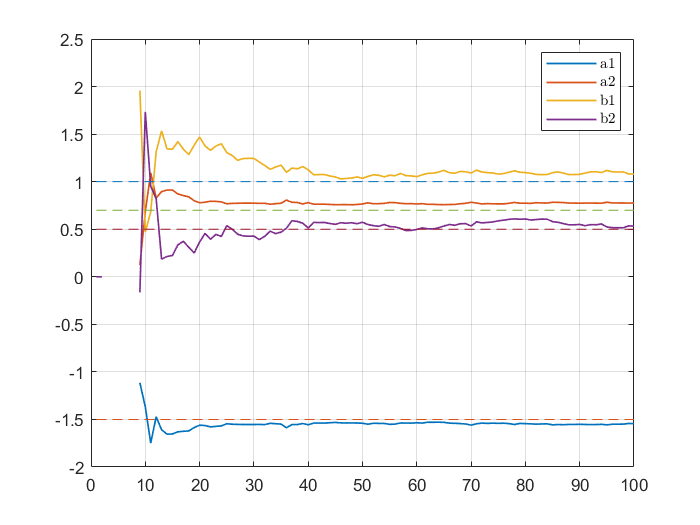

plot_estimates

**Figura 1: **Resultado de simulação para estimação dos coeficientes utilizando mínimos quadrados. N = 100. 

A Figura 1 aponta que a estimativa do vetor de parâmetros não resulta nos valores $\theta_0$ que geraram os dados. Isso pode ser justificado pela utilização de um vetor de regressores $\varphi(t)$ correlacionado com o erro de medição $e(t)$, já que utiliza-se $y(t-1)$ e $y(t-2)$ para computação do valor de saída no instante $t$. Para solucionar esse problema na estimação dos parâmetros, é possível modelar o ruído de forma mais sofisticada, como realizado nas atividades anteriores, ou utilizar o método das variáveis instrumentais.

#### Método das variáveis instrumentais - N =100

**Primeira abordagem**

Define-se o filtro $K(q)$ que gera o vetor de regressores $\xi(t) = K(q)[-x(t-1) \:\:-x(t-2) \:\:u(t-1) \:\:u(t-2)]$ e os filtros $N(q)x(t)=M(q)u(t)$como sendo  $N(q) =1, \:\: K(q)=1, \:\:M(q) =q^{-2} $. Assim, tem-se: 


$$x(k) = u(t-2)$$



$$\xi(t)=[-x(t-1) \:\:-x(t-2) \:\:u(t-1) \:\:u(t-2)]$$


A partir dos dados simulados do sistema descrito na Equação 20 , aplicou-se o método das variáveis instrumentais na estimação do vetor paramétrico. 

IV_one

ans =    -1.7205    1.1890    1.0126    0.2072


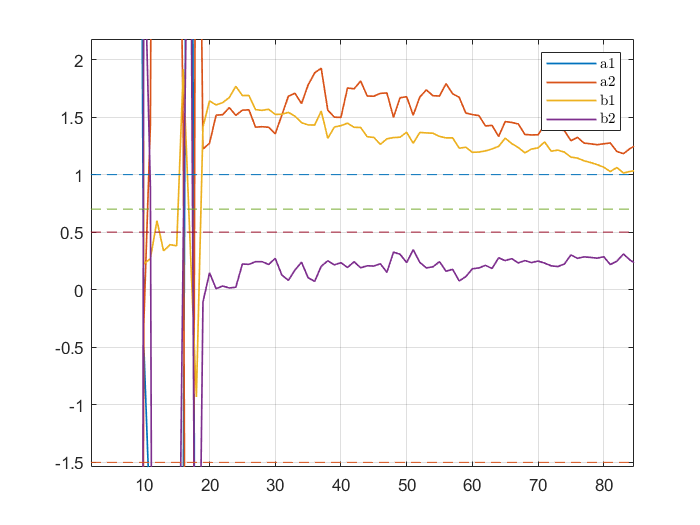

plot_estimates

**Figura 2: **Resultado de simulação para estimação dos coeficientes utilizando variáveis instrumentais - abordagem I - . N = 100.

É evidente que aproximação dos valores torna-se mais lenta quando comparada ao método de mínimos quadrados. Isso pode ser corrigido mediante uma escolha ótima dos filtros $K(q)$, $M(q)$ e $N(q)$. 

**Segunda abordagem**

Agora, modifica-se os filtros para $K(q)=1$$N(q)=1-1.5q^{-1} +0.7q^{-2} $, $M(q)=q^{-1}  + 0.5q^{-2}$. Assim:


$$x(t)=1.5x(t-1)-0.7x(t-2)+u(t-1)+0.5u(t-2)$$



$$\xi(t)=[-x(t-1) \:\:-x(t-2) \:\:u(t-1) \:\:u(t-2)]$$


Aplicou-se, novamente, o método das variáveis instrumentais na estimação do vetor paramétrico. 

IV_two
theta_IV_two(100,:)

ans =    -1.5938    0.8439    1.0796    0.4706


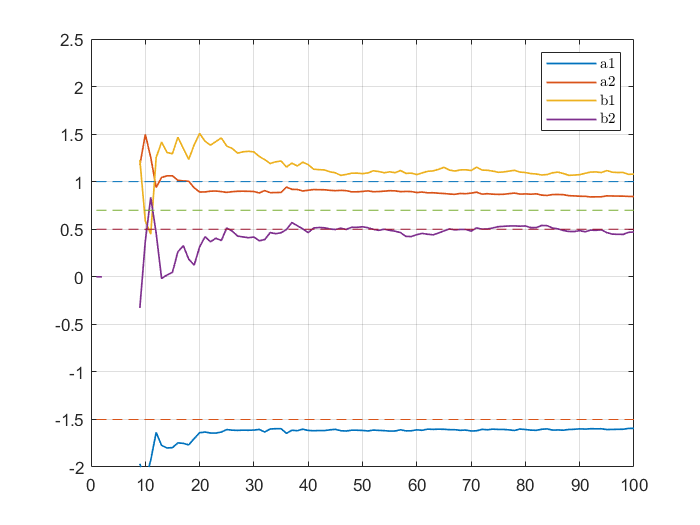

plot_estimates

**Figura 3: **Resultado de simulação para estimação dos coeficientes utilizando variáveis instrumentais - abordagem II. N = 100.

Quando compara-se a estimação ao longo do número de iterações, a aproximação dos parâmetros observada na Figura 3 é mais rápida do que a observada na Figura 2. No entanto, a estimação ainda não resulta nos valores esperados. 

**Terceira abordagem**

Agora, define-se o filtro $K(q)$ que gera o vetor de regressores $\xi(t) = K(q)[-x(t-1) \:\:-x(t-2) \:\:u(t-1) \:\:u(t-2)]$ e os filtros $N(q)x(t)=M(q)u(t)$como sendo  $K(q)=\frac{1}{1-1.5q^{-1} +0.7q^{-2} }$,$N(q)=1-1.5q^{-1} +0.7q^{-2} $, $M(q)=q^{-1}  + 0.5q^{-2}$. Assim, tem-se:


$$x(t)=1.5x(t-1)-0.7x(t-2)+u(t-1)+0.5u(t-2)$$



$$\xi(t)=1.5\xi(t-1)-0.7\xi(t-2)+[-x(t-1) \:\:-x(t-2) \:\:u(t-1) \:\:u(t-2)]$$


IV_three;
history_of_coeficients(N,:)

ans =    -1.6256    0.8665    1.1805    0.2358


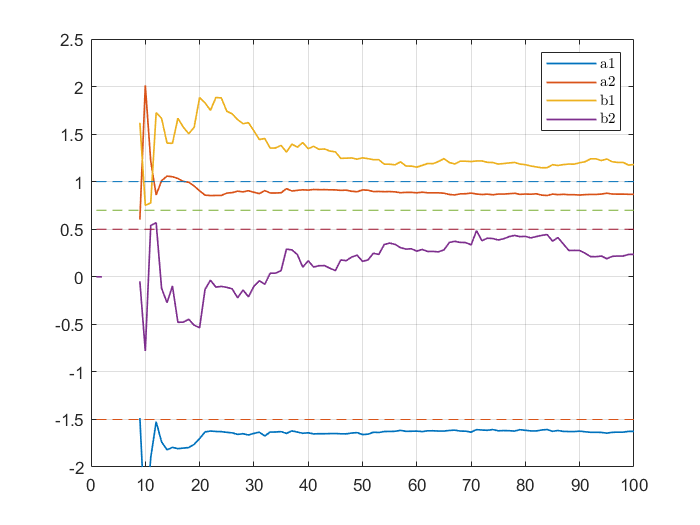

plot_estimates

**Figura 4: **Resultado de simulação para estimação dos coeficientes utilizando variáveis instrumentais - abordagem III. N = 100.

Quando avalia-se os novos filtros propostos nesta Seção, é evidente que a aproximação de valores diverge dos valores esperados para cem iterações e é pior do que o resultado obtido na Figura 1. 

#### **Método de mínimos quadrados - N =400**

Agora, varia-se o número de iterações  e avalia-se a qualidade da estimativa do vetor de parâmetros para o método de mínimos quadrados. 

warning('off','all')
N=400;
Least_squares;
history_of_coeficients_N_400=zeros(1,4);
history_of_coeficients_N_400=history_of_coeficients(N,:);
history_of_coeficients_N_400

history_of_coeficients_N_400 =    -1.4986    0.7131    1.0533    0.5010


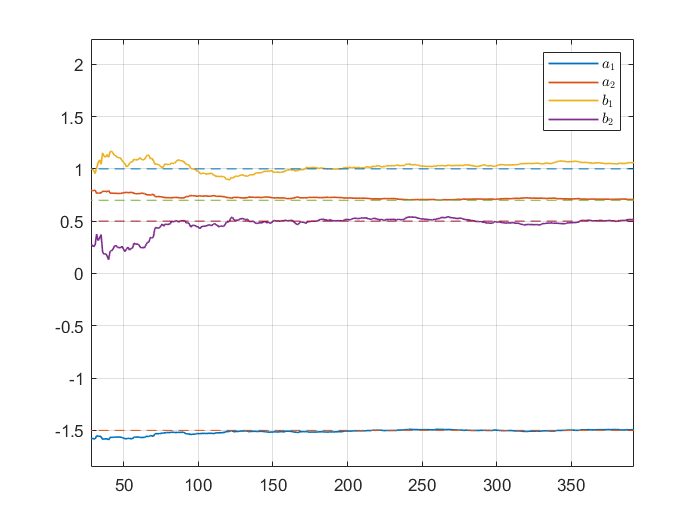

plot_estimates

**Figura 5: **Resultado de simulação para estimação dos coeficientes utilizando mínimos quadrados. N = 400. 

#### **Método das variáveis instrumentais - N =400**

Semelhantemente ao que foi feito com o método de mínimos quadrados, aumenta-se, agora, a quantidade de iterações do algoritmo de variáveis instrumentais. Utilza-se os mesmos filtros descritos nas seções Primeira abordagem, Segunda abordagem e Terceira abordagem. 

**Primeira abordagem**

IV_one

ans =    -1.4282    0.6171    1.0556    0.5705


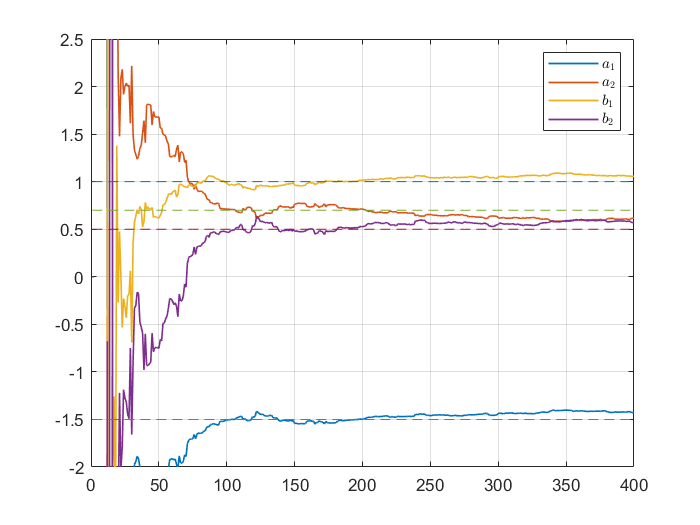

plot_estimates

**Figura 6: **Resultado de simulação para estimação dos coeficientes utilizando variáveis instrumentais - abordagem I. N = 400 

**Segunda abordagem**

IV_two
history_of_coeficients(N,:)

ans =    -1.5111    0.7269    1.0524    0.4880


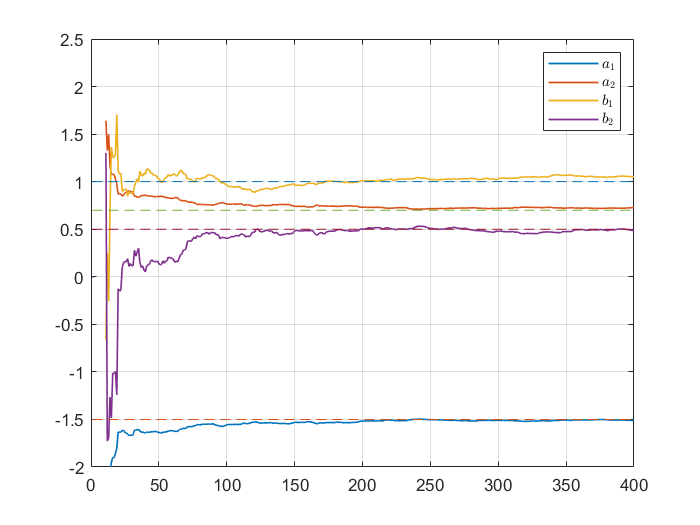

plot_estimates

**Figura 7: **Resultado de simulação para estimação dos coeficientes utilizando variáveis instrumentais - abordagem II. N = 400 

**Terceira abordagem**

IV_three
history_of_coeficients(N,:)

ans =    -1.5509    0.7587    1.0856    0.3199


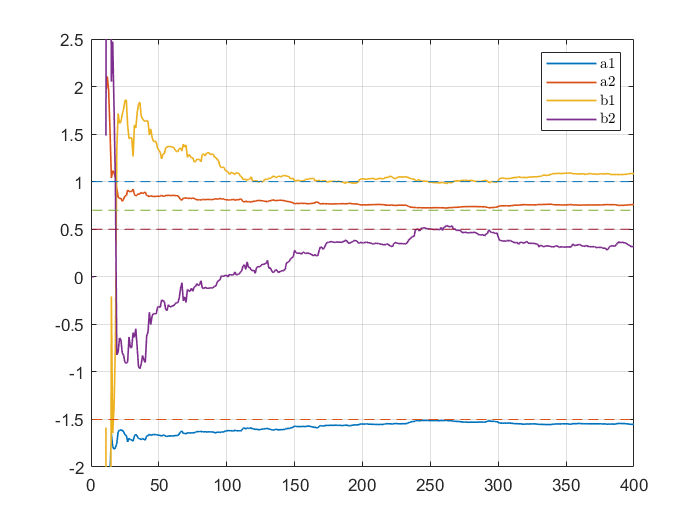

plot_estimates

**Figura 8: **Resultado de simulação para estimação dos coeficientes utilizando variáveis instrumentais - abordagem III. N = 400 

Fica claro ao aumentar o número de iterações, especialmente para a Figura 5 e para a Figura 7, resulta em uma melhor aproximação para o vetor paramétrico $\theta$. A utilização de variáveis instrumentais, no caso da segunda abordagem, com  $K(q)=1$$N(q)=1-1.5q^{-1} +0.7q^{-2} $, $M(q)=q^{-1}  + 0.5q^{-2}$, se justifica especialmente para o caso em que $N=400$. Nesse caso, a aproximação de parâmetros teve desempenho equivalente àquela obtida com o método de mínimos quadrados. Vale-se destacar que o método de variáveis instrumentais não requer a modelagem do ruído, o que pode ser útil em outros tipos de ruído incorporados à medição da saída. 

## Referências

[1]   L. LJUNG.** System Identification: Theory for the User **Courier Corporation, 2008. ISBN 0486462781.